# Fitting the Interaction Coefficient to Data

A common way of setting the value of the interaction coefficient $C_I$ in the Folgar-Tucker model is to match the value of $A_{11}$ in steady simple shear flow.  For injection molded composites, if one has data for $A_{11}$ across the thickness at some point well along the flow path, the average orientation in the shell layer should have the steady-state $A_{11}$ value in simple shear.  (This assumes that the 1 direction is the flow direction, and is known for the measured sample).  

Here is data for a polycarbonate sample with 30% by weight of short glass fibers.  The shaded regions are chosen as the shell layer, and the dashed line shows the average $A_{11}$ for these points, which is 0.8261.

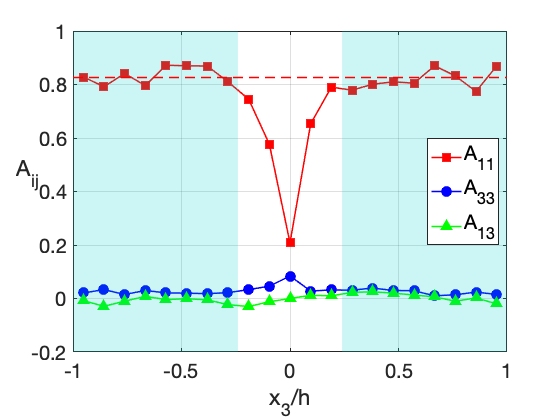

The function `fitCI` will convert this $A_{11}$ value into a $C_I$ value.  The actual value depends on the closure approximation used.  Here are some examples:

% Fit CI to the same data for a few different closures
A11 = 0.8261;   % Value extracted from experimental data
xi = 1;         % Particle shape factor
fprintf('For the natural (ORE) closure,\n')

For the natural (ORE) closure,


CInat = fitCI(A11, xi, 'N')

CInat = 0.0053

fprintf('For the IBOF closure,\n')

For the IBOF closure,


CIibof = fitCI(A11, xi, 'I')

CIibof = 0.0054

fprintf('For the ORW closure,\n')

For the ORW closure,


CIorw = fitCI(A11, xi, 'W')

CIorw = 0.0052

fprintf('For the hybrid closure,\n')

For the hybrid closure,


CIhyb = fitCI(A11, xi, 'H')

CIhyb = 0.0207

The natural and IBOF closures are some of the best closures available, and they should be used for most purposes.  Note that their $C_I$ values are close to one another, and relatively small.  The ORW closure is also quite good, and has a similar $C_I$ value.  The hybrid closure needs a much larger $C_I$ value to fit the same steady-state $A_{11}$.  The hybrid closure was popular before better closures were developed, but its use it not recommended.  

This illustrates the importance of always reporting the closure approximation used when reporting a value of $C_I$.  